Kattints az út rajzolásához! Nyomj ENTER-t a záráshoz.
Számolás: Pálya generálás...
Figyelem: Legalább 3 pont kell!


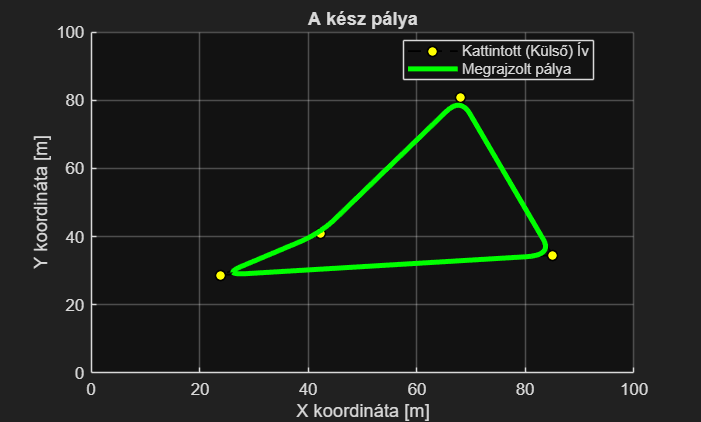

%% ============================================================
%  MAIN SCRIPT
%  ------------------------------------------------------------
%  Project name   : Tube MPC optimization with neural network
%  Author         : Bene Ádám
%  Date           : 2026.04.28.
%  Description    : Main execution script that calls the required submodules and processing steps.
%  Note           : Run this file directly.
%% ============================================================
clear;
% reference path define for the controller
run("path_define.mlx")

=== 2. FÁZIS: CasADi MPC Szimuláció és Adatgyűjtés ===
CasADi szimuláció fut... (az IPOPT megoldó dolgozik)

******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit https://github.com/coin-or/Ipopt
******************************************************************************

      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  26.00us (  2.89us)         9
       nlp_g  |        0 (       0)  53.00us (  5.89us)         9
  nlp_grad_f  |        0 (       0) 215.00us ( 21.50us)        10
  nlp_hess_l  |        0 (       0)  19.00us (  2.37us)         8
   nlp_jac_g  |        0 (       0)  28.00us (  2.80us)        10
       total  |   4.17 s (  4.17 s)   4.18 s (  4.18 s)         1
      solver  :   t_proc      (avg)   t_wal

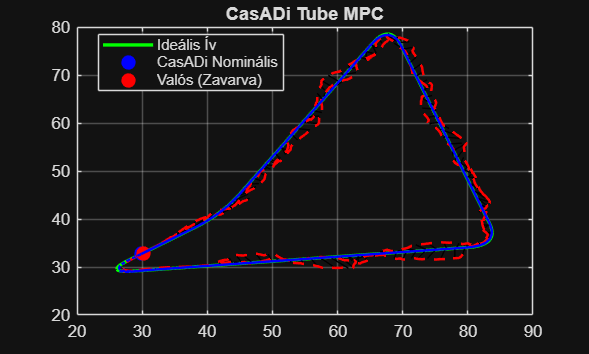


% run tube MPC for previously defined reference path for data gathering
% purposes for further ML training
run("data_gather.mlx")

=== Neurális Háló Tanítása Indul ===


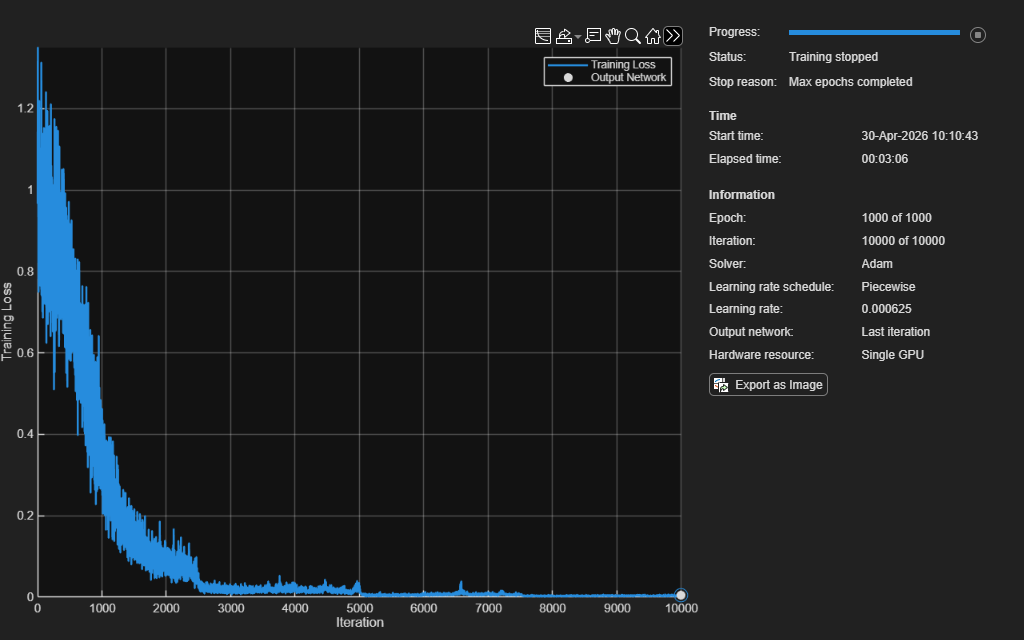

=== TANÍTÁS BEFEJEZŐDÖTT! A "net" nevű objektum elkészült. ===
--- Tesztelés az első időlépésen ---
Valós maradék hiba (a szimulációdból):
         0         0    0.1058    0.2517

Neurális háló által becsült hiba:
    0.0000   -0.0000    0.1113    0.2814




% DSDE (Dual-Stage Deep Ensemble) with 5-5 neural networks for remaining
% error minimalization, and uncertainty prediction

run("DSDE_train.mlx")
run("DSDE_test.mlx")

%NN+RL combination

% train the first NN from the offline data of the previous simulation for
% deterministic disturbances
%run("train_nn.mlx")

=== 2. Neurális Háló (Zaj-becslő / Sigma) Tanítása Indul ===


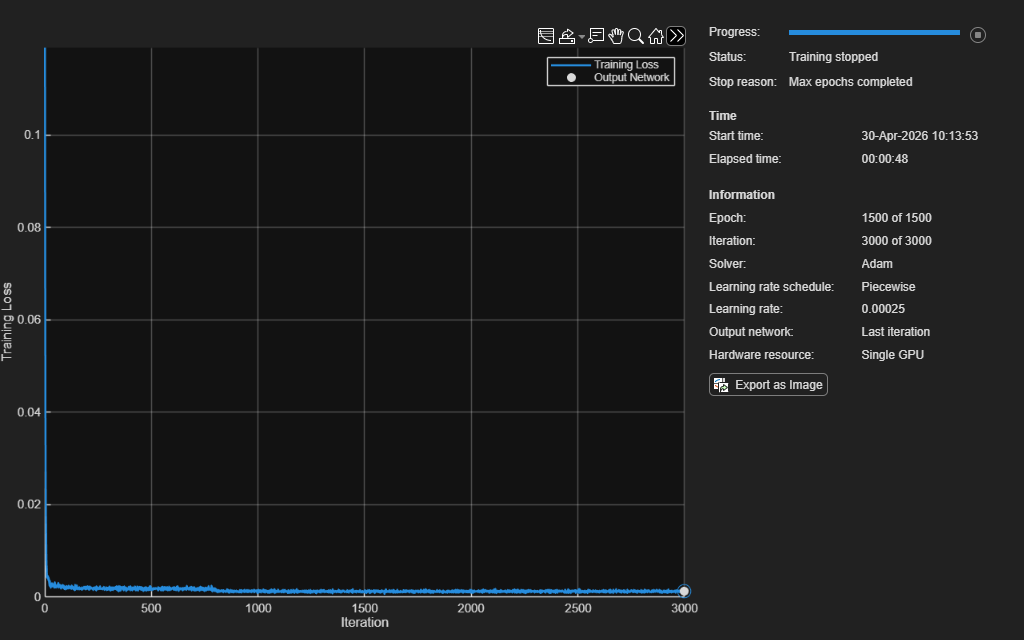

=== TANÍTÁS BEFEJEZŐDÖTT! A "net_sigma" nevű objektum elkészült. ===
--- Tesztelés az első időlépésen ---
Valós zaj mértéke (abszolút hiba az 1. hálónál) az adott pontban:
    0.0000    0.0000    0.0056    0.0297

A 2. háló (Zaj-becslő) által jósolt bizonytalanság (sigma):
         0    0.0053    0.0430    0.0464




% train a second NN from the offline data of the previous simulation for
% stochastic disturbances
%run("train_sigma_nn.mlx")


%run("ReinforcementLearning.mlx")

=== RL Tanítás: STABILIZÁLT MONITORING INDÍTVA ===


Unrecognized function or variable 'w_sigma'.

Error in ReinforcementLearning (line 63)
        obs = [x_real(1)/100; (x_real(1:2)-z_nom(1:2))/5; x_real(3:4)/10; w_sigma(3:4)/1.5];

Error in run (line 100)
evalin('caller', strcat(scriptStem, ';'));


%run("hybrid_TubeMPC_test.mlx")


